resultthree = "resultthree/";
resultmitsuba = "resultmitsuba/";
ana_result = "analysisresult/";

% 事前に定義された行列と対応する行名と列名
rowNames = {'cu_0.025', 'cu_0.129', 'pla_0.075', 'pla_0.225'};
rowNames2 = {'cu-0.025', 'cu-0.129', 'pla-0.075', 'pla-0.225'};
colNames = [19, 39, 78, 80, 102, 125, 152, 203, 226, 227, 230, 232, 243, 278, 281];

%-----------------------------------
% three parts
%-----------------------------------
threedataMatrix = zeros(4, 15);

% Excelファイル名
dirInfo = dir(resultthree);
filesNames = {dirInfo(~ismember({dirInfo(:).name}, {'.', '..'})).name};
numFiles = sum(~ismember({dirInfo(:).name}, {'.', '..'}));

for foldernum =1:numFiles
    filename = fullfile(resultthree, filesNames{foldernum});
    disp(filename);
    for materialnum = 1:length(rowNames)
        sheetName = rowNames{materialnum};
        sheetData = readtable(filename, 'Sheet', sheetName, 'ReadVariableNames', false);
        
        names = sheetData{:, 1};
        scores = sheetData{:, 2};
        
        for i = 1:length(names)
            nameStr = names{i};
            idStr = regexp(nameStr, '\d+', 'match');
            idNum = str2double(idStr(end));
            colIndex = find(colNames == idNum);
            rowIndex = find(strcmp(rowNames, sheetName));
            if ~isempty(colIndex) && ~isempty(rowIndex)
                threedataMatrix(rowIndex, colIndex) = threedataMatrix(rowIndex, colIndex) + scores(i);
            end
        end
    end
end

resultthree/kawahara_three.xlsx
resultthree/killian_three.xlsx
resultthree/kyou_three.xlsx
resultthree/miyoshi_three.xlsx
resultthree/okamoto_three.xlsx
resultthree/satou_three.xlsx



disp(threedataMatrix);

  1 列から 13 列

   -0.5584    1.1677    1.3678    1.0411    2.0263    1.4543    2.9133    0.6241   -0.7496   -2.2170   -2.1586    3.0399   -2.1871
   -1.9865    0.2459    1.2588    1.3775    3.0231    1.5629    3.1542    1.2923   -2.6587   -2.0433   -1.9296    3.0923   -0.8289
   -2.5399    0.8128    1.3564    4.1484    2.1983    2.9019   -0.5610   -0.8055   -4.2562   -3.9595    2.3299    4.0923    2.3015
   -1.9116   -0.0504   -2.0279    3.5718    0.5092    2.1536   -0.3778    0.8687   -4.7527   -1.4475    2.1696    2.7505    3.9508

  14 列から 15 列

   -4.4194   -1.3445
   -4.6578   -0.9024
   -6.9433   -1.0761
   -2.8013   -2.6051




%-----------------------------------
% mitusba parts
%-----------------------------------
mitsubadataMatrix = zeros(4, 15);

% Excelファイル名
dirInfo = dir(resultmitsuba);
filesNames = {dirInfo(~ismember({dirInfo(:).name}, {'.', '..'})).name};
numFiles = sum(~ismember({dirInfo(:).name}, {'.', '..'}));

for foldernum =1:numFiles
    filename = fullfile(resultmitsuba, filesNames{foldernum});
    disp(filename);
    for materialnum = 1:length(rowNames)
        sheetName = rowNames{materialnum};
        sheetData = readtable(filename, 'Sheet', sheetName, 'ReadVariableNames', false);
        
        names = sheetData{:, 1};
        scores = sheetData{:, 2};
        
        for i = 1:length(names)
            nameStr = names{i};
            idStr = regexp(nameStr, '\d+', 'match');
            idNum = str2double(idStr(end));
            colIndex = find(colNames == idNum);
            rowIndex = find(strcmp(rowNames, sheetName));
            if ~isempty(colIndex) && ~isempty(rowIndex)
                mitsubadataMatrix(rowIndex, colIndex) = mitsubadataMatrix(rowIndex, colIndex) + scores(i);
            end
        end
    end
end

resultmitsuba/kawahara_mitsuba.xlsx
resultmitsuba/killian_mitsuba.xlsx
resultmitsuba/kyou_mitsuba.xlsx
resultmitsuba/miyoshi_mitsuba.xlsx
resultmitsuba/okamoto_mitsuba.xlsx
resultmitsuba/satou_mitsuba.xlsx



disp(mitsubadataMatrix);

  1 列から 13 列

   -1.0459    2.6047   -0.2862    1.8894    1.7461    1.8381    1.4026    0.6562   -1.5050   -2.5019   -2.6756    1.4594    0.7250
   -1.0019    0.1987    0.2001    2.3028    0.7597    1.9458    2.1335    1.2859   -2.7240   -2.3606   -0.1593    1.4887    1.6334
   -2.5117   -0.0916   -0.6352    3.6517    1.1970    2.4842    0.6237    3.6309   -3.9239   -2.3524    1.4940    3.4847    2.6492
   -2.6157   -2.5994   -1.4109    2.9290   -0.8747    0.8115    0.7226    5.4035   -4.4883   -3.6326   -0.5188    2.6436    3.3429

  14 列から 15 列

   -2.7539   -1.5529
   -5.0319   -0.6709
   -5.8956   -3.8052
   -0.0632    0.3507



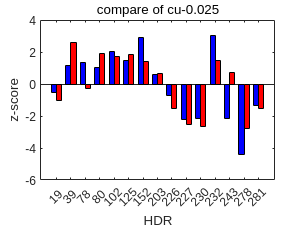

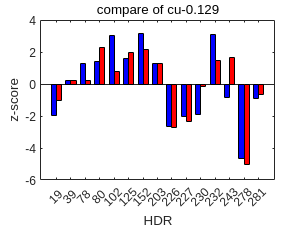

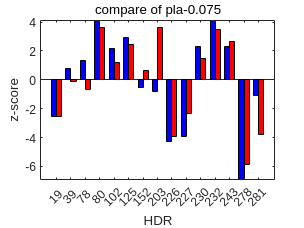

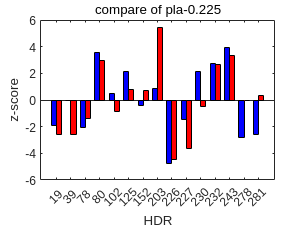

%-----------------------------------
% analysis
%-----------------------------------
%bar graph
for row = 1:4
    figure;
    bar_width = 0.35;
    x = 1:length(colNames);

    % threedataのプロット
    bar(x - bar_width/2, threedataMatrix(row, :), bar_width, 'FaceColor', 'b', 'DisplayName', 'three'); 
    hold on;
    
    % mitsubadataのプロット
    bar(x + bar_width/2, mitsubadataMatrix(row, :), bar_width, 'FaceColor', 'r', 'DisplayName', 'mitsuba'); 
    
    set(gca, 'XTick', 1:length(colNames));
    set(gca, 'XTickLabel', colNames);
    xlabel('HDR'); 
    ylabel('z-score');
    title(['compare of ' rowNames2{row}]);
    %legend('show');
end


%correlation_coefficients
correlation_coefficients = zeros(1, 4);
for row = 1:4
    data_three = threedataMatrix(row, :);
    data_mitsuba = mitsubadataMatrix(row, :);
    corr_matrix = corrcoef(data_three, data_mitsuba);
    correlation_coefficients(row) = corr_matrix(1, 2);
end

disp(correlation_coefficients);

    0.8068    0.8536    0.8618    0.6929

